## **BE 2 : Image processing - frequency domain**

**A. Image filtering**

**Exercise 1 – 2-D Fourier Transform**

**A.1.1**

**Commençons par l'image Fig_Moon.tif : **

% Charger l'image de la Lune
image_lune = imread("Fig_Moon.tif",'tiff');

% Convertir en niveaux de gris
image_lune_gray = image_lune(:,:,1);

% Afficher l'image d'origine
figure(1), subplot(221), imshow(image_lune_gray);
title('Image originale de la Lune');

% Calculer la magnitude du spectre de l'image et l'afficher
spectre_lune = abs(fftshift(fft2(image_lune_gray)));
subplot(222), imshow(spectre_lune, []);
title('Magnitude de la transformée de Fourier 2D');
xlabel('Fréquence horizontale'), ylabel('Fréquence verticale');

% Déterminer les valeurs minimale et maximale du spectre
spectre_min = min(min(spectre_lune));
spectre_max = max(max(spectre_lune));
fprintf('Valeur minimale et maximale du spectre : %f %f \n', spectre_min, spectre_max);

Valeur minimale et maximale du spectre : 1.174348 10078527.000000 


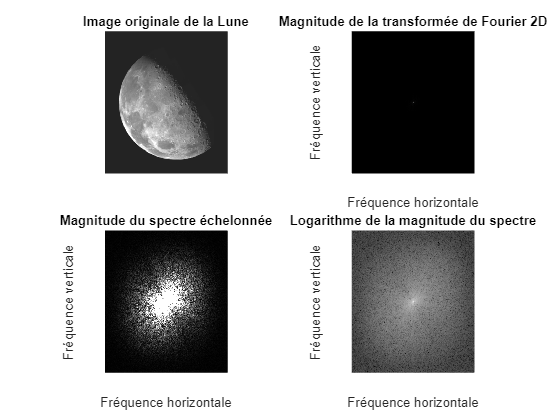


% Afficher le spectre en échelle logarithmique
subplot(223), imshow(spectre_lune, [1.5*spectre_min, spectre_max*1.e-3]);
title('Magnitude du spectre échelonnée');
xlabel('Fréquence horizontale'), ylabel('Fréquence verticale');

% Afficher le spectre en échelle logarithmique
subplot(224), imshow(log(spectre_lune+1), []);
title('Logarithme de la magnitude du spectre');
xlabel('Fréquence horizontale'), ylabel('Fréquence verticale');

**Passons maintenant à faire le même code pour l'image Fig_woman.tif :**

% Charger l'image de la Femme
image_femme = imread("Fig_woman.tif",'tiff');

% Convertir en niveaux de gris
image_femme_gray = image_femme(:,:,1);

% Afficher l'image d'origine
figure(2), subplot(221), imshow(image_femme_gray);
title('Image originale de la Femme');

% Calculer la magnitude du spectre de l'image et l'afficher
spectre_femme = abs(fftshift(fft2(image_femme_gray)));
subplot(222), imshow(spectre_femme, []);
title('Magnitude de la transformée de Fourier 2D');
xlabel('Fréquence horizontale'), ylabel('Fréquence verticale');

% Déterminer les valeurs minimale et maximale du spectre
spectre_min_femme = min(min(spectre_femme));
spectre_max_femme = max(max(spectre_femme));
fprintf('Valeur minimale et maximale du spectre : %f %f \n', spectre_min_femme, spectre_max_femme);

Valeur minimale et maximale du spectre : 9.125552 17552349.000000 


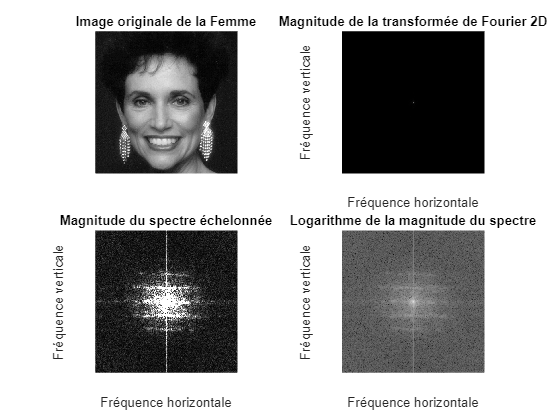


% Afficher le spectre en échelle logarithmique
subplot(223), imshow(spectre_femme, [1.5*spectre_min_femme, spectre_max_femme*1.e-3]);
title('Magnitude du spectre échelonnée');
xlabel('Fréquence horizontale'), ylabel('Fréquence verticale');

% Afficher le spectre en échelle logarithmique
subplot(224), imshow(log(spectre_femme+1), []);
title('Logarithme de la magnitude du spectre');
xlabel('Fréquence horizontale'), ylabel('Fréquence verticale');

**Enfin, on termine avec l'image Fig_xray.tif :**

% Charger l'image de la Radiographie
image_radiographie = imread("Fig_xray.tif",'tiff');

% Convertir en niveaux de gris
image_radiographie_gray = image_radiographie(:,:,1);

% Afficher l'image d'origine
figure(3), subplot(221), imshow(image_radiographie_gray);
title('Image originale de la Radiographie');

% Calculer la magnitude du spectre de l'image et l'afficher
spectre_radiographie = abs(fftshift(fft2(image_radiographie_gray)));
subplot(222), imshow(spectre_radiographie, []);
title('Magnitude de la transformée de Fourier 2D');
xlabel('Fréquence horizontale'), ylabel('Fréquence verticale');

% Déterminer les valeurs minimale et maximale du spectre
spectre_min_radiographie = min(min(spectre_radiographie));
spectre_max_radiographie = max(max(spectre_radiographie));
fprintf('Valeur minimale et maximale du spectre : %f %f \n', spectre_min_radiographie, spectre_max_radiographie);

Valeur minimale et maximale du spectre : 0.000000 32839326.000000 


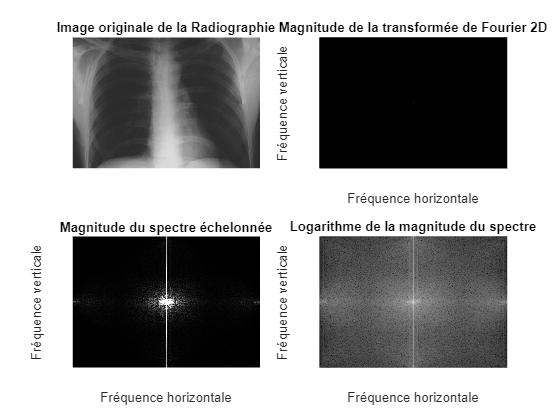


% Afficher le spectre en échelle logarithmique
subplot(223), imshow(spectre_radiographie, [1.5*spectre_min_radiographie, spectre_max_radiographie*1.e-3]);
title('Magnitude du spectre échelonnée');
xlabel('Fréquence horizontale'), ylabel('Fréquence verticale');

% Afficher le spectre en échelle logarithmique
subplot(224), imshow(log(spectre_radiographie+1), []);
title('Logarithme de la magnitude du spectre');
xlabel('Fréquence horizontale'), ylabel('Fréquence verticale');

**A.1.2.**

**Les caractéristiques d'une image sont souvent reflétées dans le tracé de la magnitude de sa transformée de Fourier 2D (TFD). Par exemple :**

**Détection des bords : Les transitions ou les bords nets dans une image se traduisent par des composantes haute fréquence dans le tracé de la magnitude de la TFD. Ainsi, un filtre passe-haut dans le domaine fréquentiel peut être utilisé pour accentuer ou détecter ces bords.**

**Périodicité : Les motifs ou les structures répétitifs dans une image se manifestent sous forme de pics dans le tracé de la magnitude de la TFD. La distance entre ces pics correspond à la fréquence spatiale du motif ou de la structure.**

**Flou : Le flou d'une image se traduit par un lissage des composantes haute fréquence dans le domaine fréquentiel. Par conséquent, un filtre passe-bas peut être utilisé pour obtenir un effet similaire de flou.**

**Compression :Lors de la compression d'une image, les composantes haute fréquence sont souvent réduites ou quantifiées avec moins de précision. Ainsi, le tracé de la magnitude de la TFD d'une image compressée peut montrer une réduction des composantes haute fréquence par rapport à l'image d'origine.**

**Rotation :La rotation d'une image entraîne une rotation de ses composantes fréquentielles dans le domaine de la fréquence. Par conséquent, le tracé de la magnitude de la TFD d'une image tournée aura des pics également tournés, reflétant l'angle de rotation de l'image.**

**Exercise 2 - Importance of DFT Phase**

L'angle de phase de la transformée de Fourier d'une image contient de nombreuses informations sur l'image.

**A.2.1.**

% Charger l'image de la barre500
image_barre = imread('Fig_Barre500.tif','tiff');

figure(4)

% Afficher l'image originale
subplot(221), imshow(image_barre, []), title('Image originale');

% Afficher une deuxième fois l'image originale (à des fins de comparaison)
subplot(223), imshow(image_barre, []), title('Image originale');

% Transformation de l'image dans le domaine fréquentiel et calcul de la magnitude et de la phase
F = fftshift(fft2(image_barre)); % Transformée de Fourier de l'image
magnitude_F = abs(F); % Magnitude de la transformée de Fourier
phase_F = atan2(imag(F), real(F)); % Phase de la transformée de Fourier
F_phase = exp(1i*phase_F); % Reconstruction de la phase

% Conversion uniquement de la magnitude et uniquement de la phase en images
magnitude_seulement = real(ifft2(magnitude_F)); % Reconstruction de l'image à partir de la magnitude uniquement
phase_seulement = real(ifft2(F_phase)); % Reconstruction de l'image à partir de la phase uniquement

% Détermination des valeurs maximale et minimale de l'image de magnitude et affichage
Fmax = max(max(magnitude_seulement));
Fmin = min(min(magnitude_seulement));
fprintf('Fmin, Fmax: %f %f', Fmin, Fmax);

Fmin, Fmax: -1090.711174 1527.532404

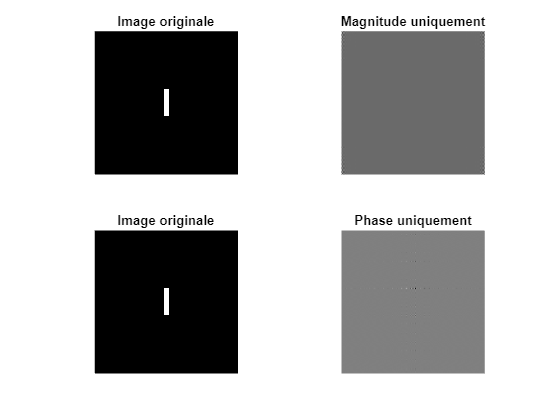


% Conversion de l'image de magnitude uniquement et de l'image de phase uniquement en format uint8 pour l'affichage
magnitude_seulement_uint8 = im2uint8(mat2gray(magnitude_seulement));
phase_seulement_uint8 = im2uint8(mat2gray(phase_seulement));

% Affichage de l'image de magnitude uniquement
subplot(222), imshow(magnitude_seulement_uint8), title('Magnitude uniquement');

% Affichage de l'image de phase uniquement
subplot(224), imshow(phase_seulement_uint8), title('Phase uniquement');

% Woman

% Charger l'image
image_woman = imread('Fig_woman.tif','tiff');

figure(5)

% Afficher l'image originale deux fois
subplot(221), imshow(image_woman, []), title('Image originale');
subplot(223), imshow(image_woman, []), title('Image originale');

% Transformation de l'image dans le domaine fréquentiel et calcul de la magnitude et de la phase
F_woman = fftshift(fft2(image_woman)); % Transformée de Fourier de l'image
magnitude_F_woman = abs(F_woman); % Magnitude de la transformée de Fourier
phase_F_woman = atan2(imag(F_woman), real(F_woman)); % Phase de la transformée de Fourier
F_phase_woman = exp(1i*phase_F_woman); % Reconstruction de la phase

% Conversion uniquement de la magnitude et uniquement de la phase en images
magnitude_seulement_woman = real(ifft2(magnitude_F_woman)); % Reconstruction de l'image à partir de la magnitude uniquement
phase_seulement_woman = real(ifft2(F_phase_woman)); % Reconstruction de l'image à partir de la phase uniquement

% Détermination des valeurs maximale et minimale de l'image de magnitude et affichage
GMax = max(max(magnitude_seulement_woman));
GMin = min(min(magnitude_seulement_woman));
fprintf('GMin, GMax: %f %f', GMin, GMax);

GMin, GMax: -2162.993996 4181.600460

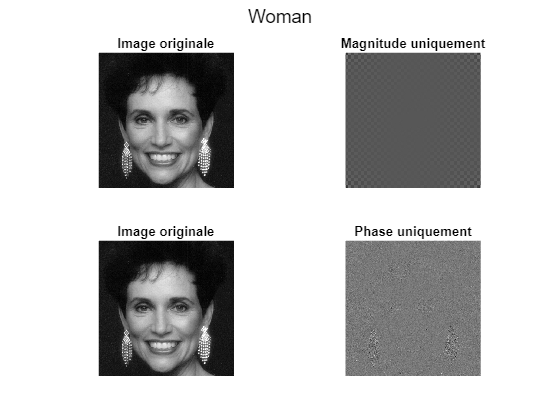


% Conversion de l'image de magnitude uniquement et de l'image de phase uniquement en format uint8 pour l'affichage
magnitude_seulement_woman_uint8 = im2uint8(mat2gray(magnitude_seulement_woman));
phase_seulement_woman_uint8 = im2uint8(mat2gray(phase_seulement_woman));

% Affichage de l'image de magnitude uniquement
subplot(222), imshow(magnitude_seulement_woman_uint8), title('Magnitude uniquement');

% Affichage de l'image de phase uniquement
subplot(224), imshow(phase_seulement_woman_uint8), title('Phase uniquement');

% Titre global de la figure
sgtitle('Woman');

**A.2.2. **

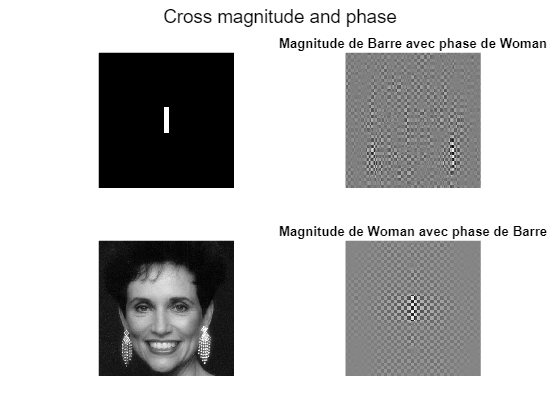

%Interchanging magnitudes and phases
F1 = FA.*GB;
G1 = GA.*FB;
f1r = im2uint8(mat2gray(real(ifft2(F1))));
g1r = im2uint8(mat2gray(real(ifft2(G1))));

figure(7)
subplot(221), imshow(r, []);
subplot(222), imshow(f1r, []), title('Magnitude de Barre avec phase de Woman');
subplot(223), imshow(q, []);
subplot(224), imshow(g1r, []), title('Magnitude de Woman avec phase de Barre');
sgtitle('Cross magnitude and phase')

**A.2.3.**

On voit qu'en général les traits que l'on retrouve le plus sont ceux dus à la phase que à la magnitude.

**Exercise 3 - Linear Filtering of Images**

%Choosing values for M, N, cutoff

M = 720;
N = 720;
cutoff = 100;

**Filters :**

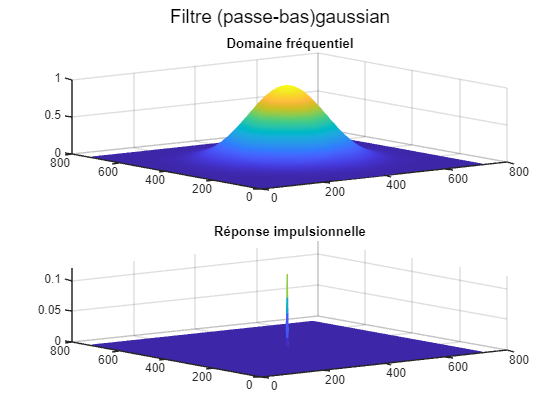

H1 = linear_filter('gaussian', M, N, cutoff, 0);

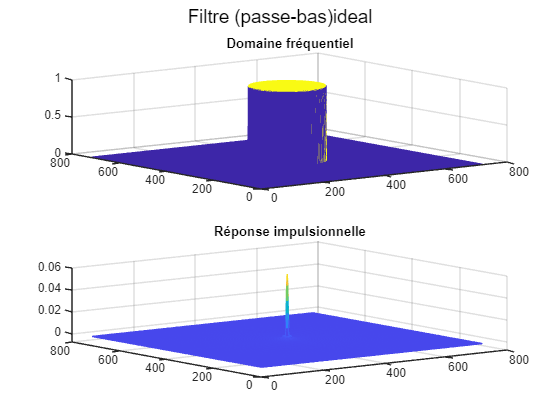

H2 = linear_filter('ideal', M, N, cutoff, 0);

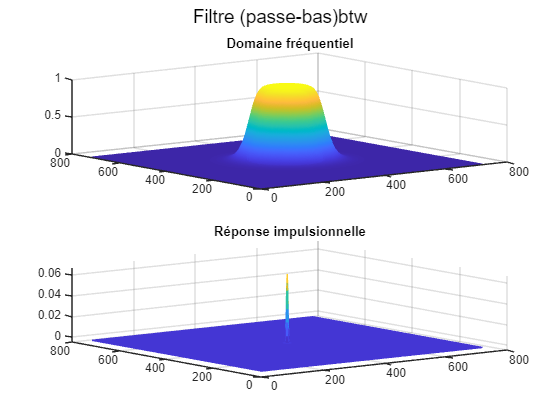

H3 = linear_filter('btw', M, N, cutoff, 4);

**A.3.1.**

Le filtre a une réponse entre 0 et 1, il suffit donc de prendre la valeur 1 et de lui soustraire le filtre pour obtenir le filtre passe-haut complémentaire.

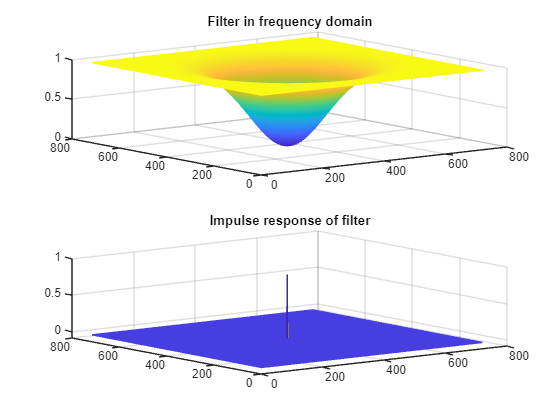

highH1 = 1 - lpfilter('gaussian', M, N, cutoff, 0);
figure; subplot(211); mesh(fftshift(highH1));
title("Filter in frequency domain")

highh1 = ifft2(highH1);
subplot(212); mesh(fftshift(highh1));
 title("Impulse response of filter")

**A.3.2.**

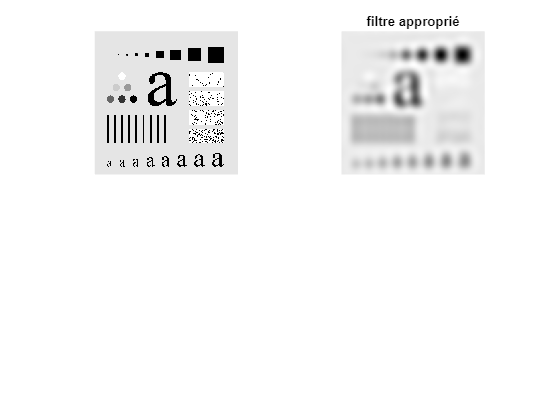

figtest = imread('Fig_test_pattern.tif', 'tiff');

figure
subplot(221), imshow(figtest);

[M,N] = size(figtest);

approH = lpfilter('btw', M, N, 10, 4); %filtre approprié

productfilt = fft2(figtest).*approH;

figtest_filt = im2uint8(mat2gray(ifft2(productfilt)));

subplot(222), imshow(figtest_filt);

title('filtre approprié')

**A.3.3.**

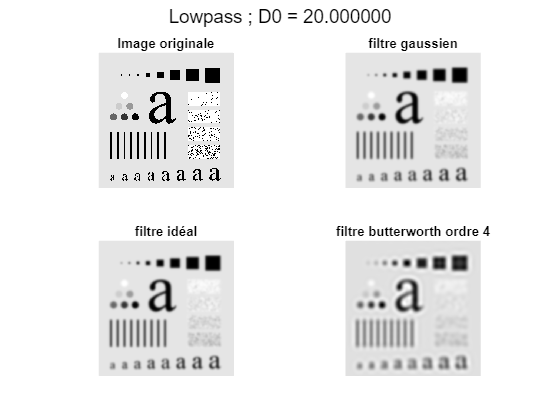

% D0 = 20
D0 = 20;
comparisonFilt(figtest, D0);

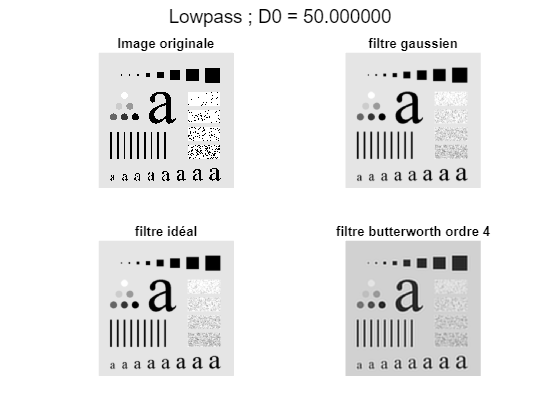


% D0 = 50
D0 = 50;
comparisonFilt(figtest, D0);

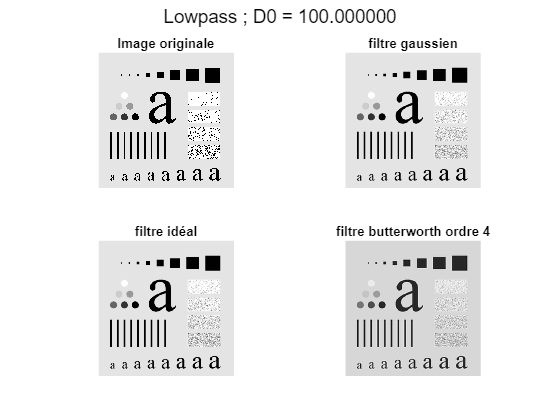


%D0 = 100
D0 = 100;
comparisonFilt(figtest, D0);

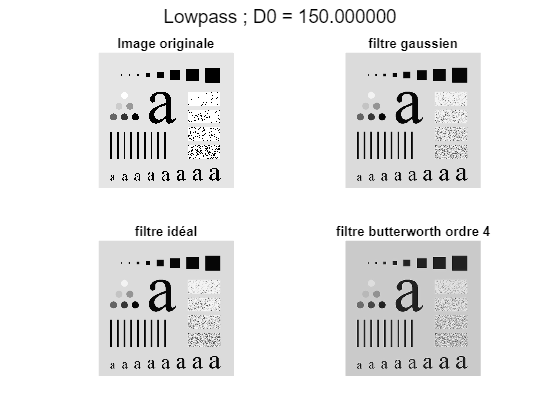


%D0 = 150
D0 = 150;
comparisonFilt(figtest, D0);

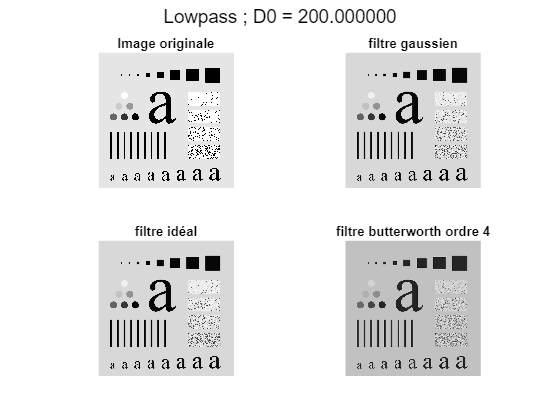


%D0 = 200
D0 = 200;
comparisonFilt(figtest, D0);

Filtrage passe-bas semble flouter l'image.

**A.3.4.**

La même chose avec les filtres passe-haut :

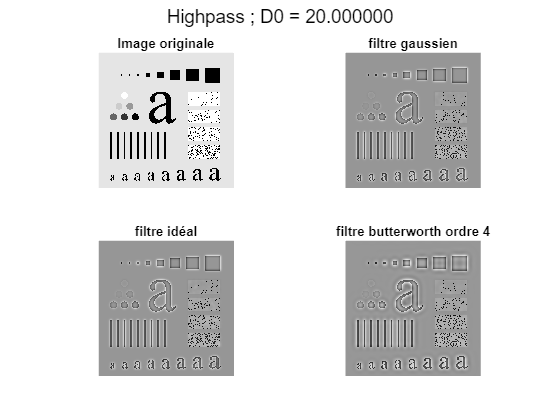


% D0 = 20
D0 = 20;
comparisonFiltHigh(figtest, D0);

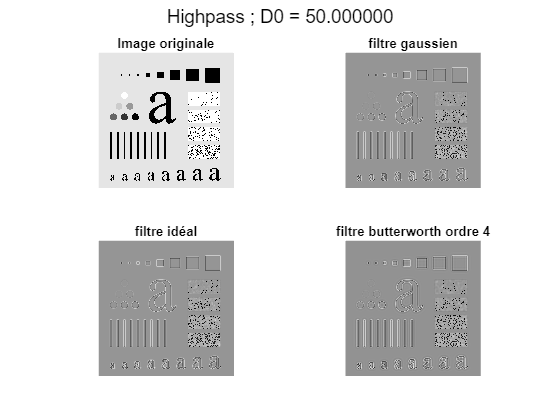


% D0 = 50
D0 = 50;
comparisonFiltHigh(figtest, D0);

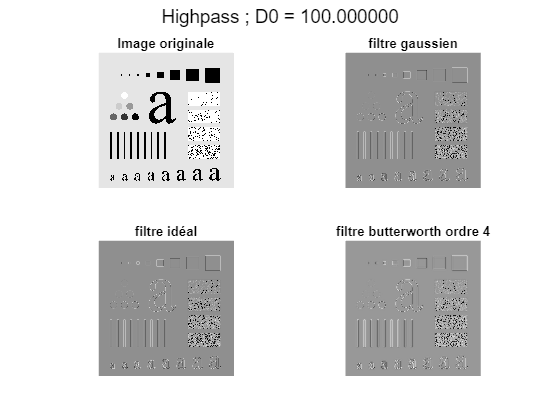


%D0 = 100
D0 = 100;
comparisonFiltHigh(figtest, D0);

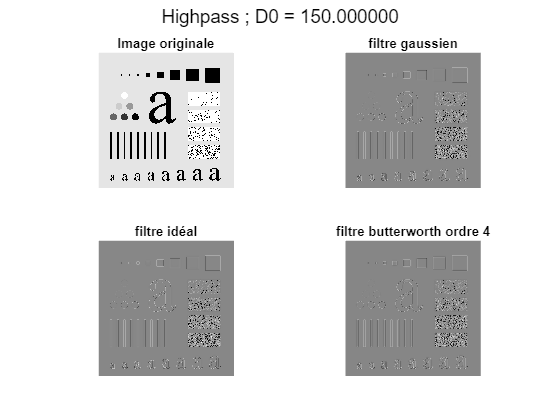


%D0 = 150
D0 = 150;
comparisonFiltHigh(figtest, D0);

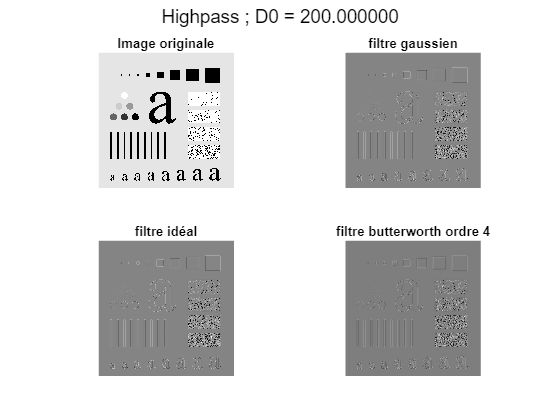


%D0 = 200
D0 = 200;
comparisonFiltHigh(figtest, D0);